##   Oceanus - Test Frame Search Process

Author: Michel Barbeau, Carleton University

Draft version: February 27, 2021

### Read wave file

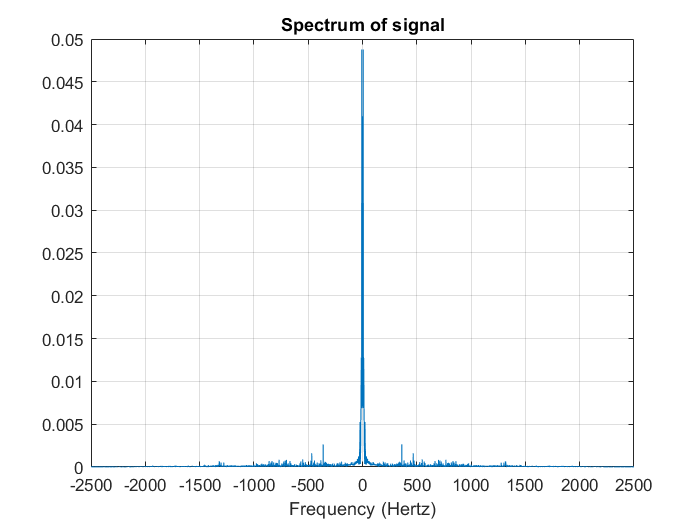

clear;
%%%% Arctic 2012 Data
% Originaly, the signal had been recorded at carrier frequency is 360 Hz at 4,500 sps.
% When it was replaid during the sea trial (August 2019), the signal has been re-sampled [Stephane] 
% with an interpolation on factor off 22, taking it to 22 * 4,500 = 99,000 sps.
% The signals had been played at 100,000 sps [Stéphane], accelerating them by a factor of 100/99.
%
% A rational resampler (Interpolation: 8, Decimination: 5) resample from 5,000 sps to 8,000 sps. 
% A correction is added, due to accelerated playback: 100/99 * 360 Hz = 4 Hz.
% Center Frequency is set to 364 Hz.
% Tests with WAV files
% OK
% WavFileName = "TXtime_2019_08_29_11_43_00_Signal06_Occur23__Hp01_Range12_PercentClip000_RangeMeters11857_RXtime_2019_08_29_11_43_07_000.wav";
% NOK
% WavFileName = "TXtime_2019_08_29_01_01_14_Signal01_Occur01__Hp01_Range15_PercentClip000_RangeMeters14422_RXtime_2019_08_29_01_01_24_000.wav";
% NOK
% WavFileName = "TXtime_2019_08_29_05_04_17_Signal09_Occur09__Hp06_Range31_PercentClip009_RangeMeters30531_RXtime_2019_08_29_05_06_06_000.wav";
% Tests with FLAC files
% NOK
% WavFileName = "TXtime_2019_08_29_11_37_32_Signal04_Occur23__Hp01_Range12_PercentClip000_RangeMeters11780_RXtime_2019_08_29_11_37_40_000.flac";
% OK
WavFileName = "TXtime_2019_08_29_11_43_00_Signal06_Occur23__Hp01_Range12_PercentClip000_RangeMeters11857_RXtime_2019_08_29_11_43_07_000.flac";
% NOK
% WavFileName = "TXtime_2019_08_29_11_15_09_Signal06_Occur22__Hp01_Range13_PercentClip000_RangeMeters12548_RXtime_2019_08_29_11_15_17_000.flac";
% NOK
% WavFileName = "TXtime_2019_08_29_11_09_41_Signal04_Occur22__Hp01_Range13_PercentClip000_RangeMeters12829_RXtime_2019_08_29_11_09_49_000.flac";
% NOK
% WavFileName = "TXtime_2019_08_29_01_22_53_Signal09_Occur01__Hp01_Range14_PercentClip000_RangeMeters13985_RXtime_2019_08_29_01_23_02_000.flac";
% NOK
% WavFileName = "TXtime_2019_08_29_01_22_53_Signal09_Occur01__Hp01_Range14_PercentClip000_RangeMeters13985_RXtime_2019_08_29_01_23_02_000.flac";
% NOK
% WavFileName = "TXtime_2019_08_29_01_01_14_Signal01_Occur01__Hp01_Range15_PercentClip000_RangeMeters14422_RXtime_2019_08_29_01_01_24_000.flac";
% NOK
% WavFileName = "TXtime_2019_08_29_03_21_15_Signal01_Occur07__Hp03_Range20_PercentClip000_RangeMeters19116_RXtime_2019_08_29_03_21_27_000.flac";
% NOK
% WavFileName = "TXtime_2019_08_29_08_43_36_Signal01_Occur18__Hp01_Range26_PercentClip003_RangeMeters25984_RXtime_2019_08_29_08_43_54_000.flac";
% Center Frequency (Hertz)
cf = 360;
% Half bandwidth (Hertz)
hb = 10;
%%% Plot the data in the frequency domain ("fs" is sample rate)
[x,fs] = audioread(WavFileName);
% remove sea trial playback acceleration 
x1 = resample(x,100,99); 
% skip the 1st 20 seconds (Stéphane's preamble)
startp = 21*fs+1;
x2 = x1(startp:length(x1)); 
% x2 = x1;
% keep a window of two minutes
x3 = x2(1:fs*120);
FFTSIZE=fs;
N=length(x3); % number of sambles (mode*60 seconds of signal)
y=fft(x3,FFTSIZE)/FFTSIZE; % FFT
figure; 
% plot(f,abs([y(N/2+1:N)', y(1:N/2)']));
plot([-FFTSIZE/2:1:-1 0:1:FFTSIZE/2-1], abs([y(FFTSIZE/2+1:FFTSIZE)', y(1:FFTSIZE/2)']));
title('Spectrum of signal');
xlabel("Frequency (Hertz)");
grid on;

Downconversion to baseband (complex envelope):

% cutoffFrequency = 150; % Hertz
% Wn = (2/1000)*cutoffFrequency;
% lowPassfilter = fir1(20,Wn,'low',kaiser(21,3));
% fvtool(lowPassfilter,1,'Fs',fs);
% create bandpass filter
bandpassSpecs = fdesign.bandpass('N,Fst1,Fp1,Fp2,Fst2,C',400,cf-50,cf-hb,cf+hb,cf+50,5000);
% Constrain the two stopbands with a stopband attenuation of 60 dB
bandpassSpecs.Stopband1Constrained = true;
bandpassSpecs.Astop1 = 60;
bandpassSpecs.Stopband2Constrained = true;
bandpassSpecs.Astop2 = 60;
% Design the bandpass filter using the design function
bandpassFilter = design(bandpassSpecs,'Systemobject',true);
% Visualize the frequency response 
% fvtool(bandpassFilter);
% filter the data 
% x3filtered = filter(bandpassFilter,1,x3);
x3filtered = bandpassFilter(x3);
% up sample from 5,000 sps to 6,000 sps
x4 = resample(x3filtered,6,5); 

Downconversion to baseband (complex envelope):

Decimation factor (16) takes sampling down to 375 sps.

dwnConv = dsp.DigitalDownConverter(...
  'DecimationFactor',16,...  
  'SampleRate', 6000,...
  'Bandwidth', 187,...
  'StopbandAttenuation', 55,...
  'PassbandRipple',0.2,...
  'CenterFrequency',cf); % frequency translation offset

Plot the spectrum:

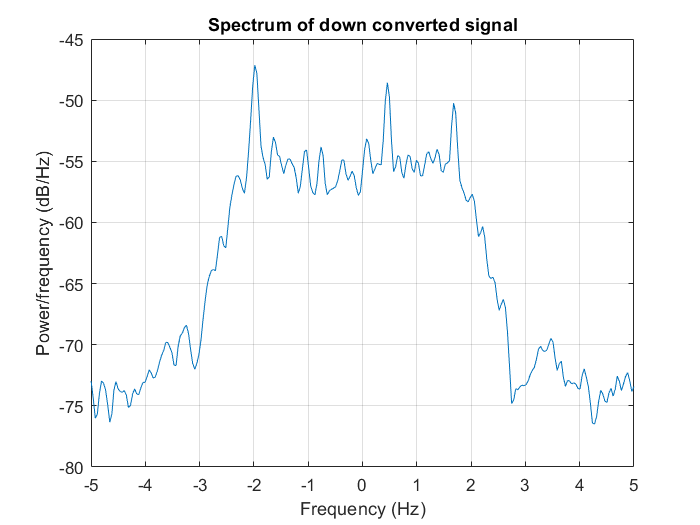

xDown = dwnConv(x4); % down convert
window = hamming(floor(length(xDown)/10));
figure; pwelch(xDown,window,[],[],fs/16,'centered');
title('Spectrum of down converted signal');
xlim([-5 5])

Frame search

Number of FFTs is 348 (should be 348)
FFT size is 512 bins (should be mode (in minutes) times 256)
delta f is 0.7324222.2 Hz


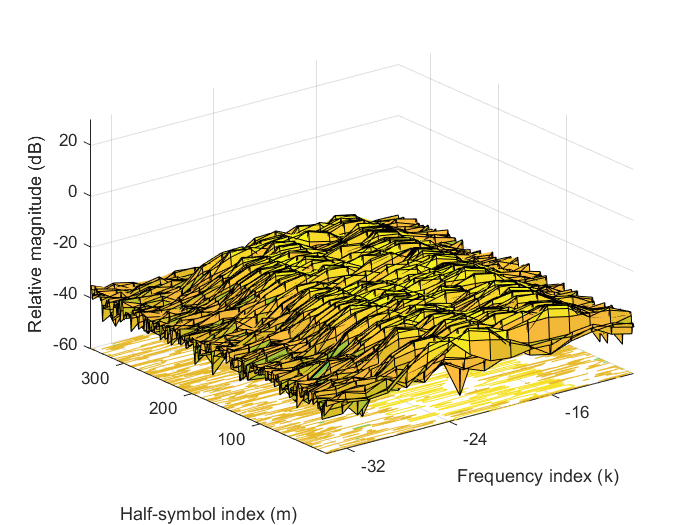

d is 3
Number of smoothed frequencies is 506


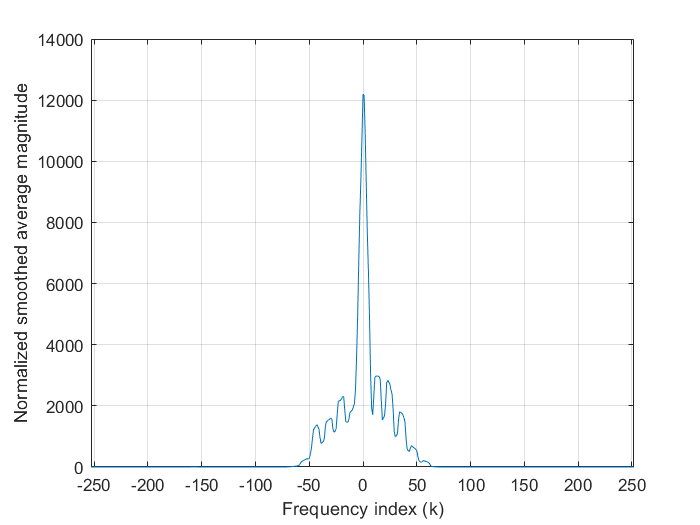

The number of candidates is 300
[index 6-Hz-SNR(dB)]
[-205 -6.87] [-195 -4.22] [-194 -0.10] [-193 0.34] [-192 0.41] [-191 0.36] [-190 0.17] [-189 -0.43] [-188 -3.77] [-179 -5.11] [-178 -3.98] [-177 -4.84] [-161 -1.96] [-160 3.10] [-159 3.99] [-158 4.12] [-157 4.15] [-156 4.07] [-155 3.81] [-154 2.48] [-153 -4.63] [-150 -5.82] [-149 0.57] [-148 1.92] [-147 2.26] [-146 2.52] [-145 2.80] [-144 2.94] [-143 1.75] [-142 -1.92] [-141 -5.41] [-140 -5.71] [-139 -5.97] [-128 -4.90] [-127 -0.76] [-126 1.63] [-125 2.11] [-124 1.98] [-123 1.66] [-122 1.29] [-121 0.71] [-120 -1.79] [-115 -3.64] [-114 -1.15] [-113 -0.53] [-112 -0.28] [-111 0.04] [-110 0.13] [-109 -0.22] [-108 -2.36] [-107 -5.50] [-103 -5.38] [-102 -4.58] [-101 -3.79] [-100 -2.64] [-99 -1.05] [-98 -0.38] [-97 -0.37] [-96 -1.10] [-95 -1.15] [-94 -1.27] [-93 -1.60] [-92 -2.69] [-91 -3.58] [-90 -4.43] [-89 -4.79] [-88 -4.65] [-87 -4.15] [-86 -3.43] [-85 -2.73] [-84 -1.99] [-83 -1.49] [-82 -1.11] [-81 -0.67] [-80 -0.52] [-79 -0.72] [-78 -

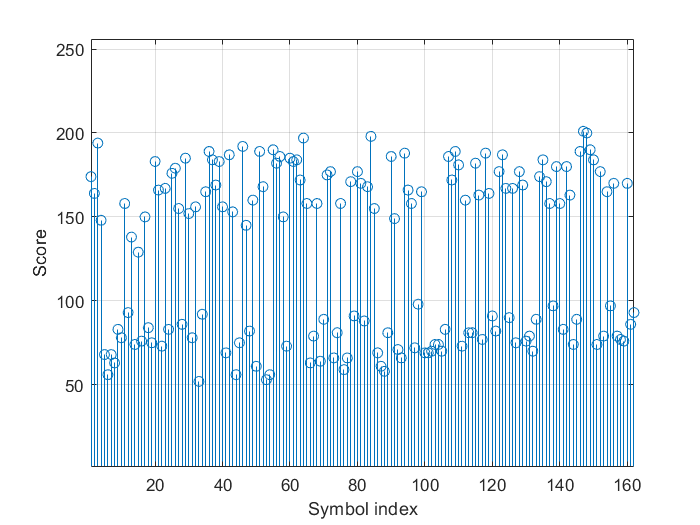

Scores first 12 channel symbols
 174  164  194  148  68  56  68  63  83  78  158  93 


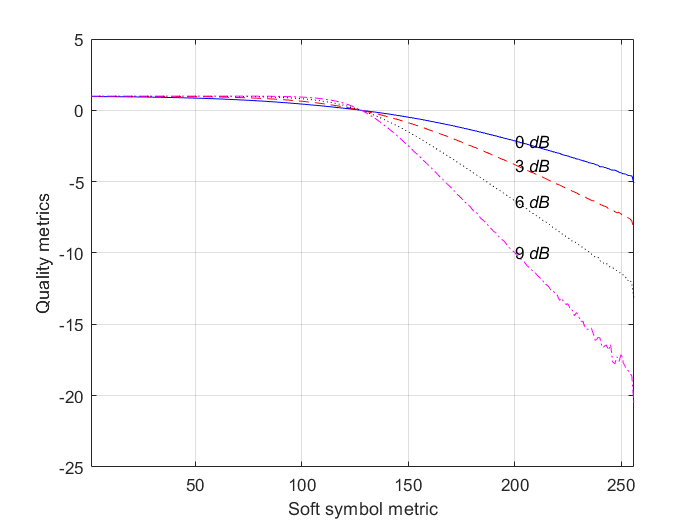

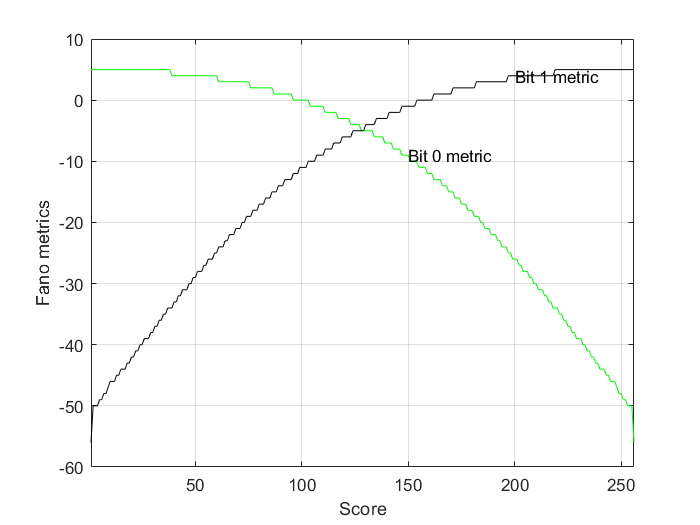

K=32; % constraint
% message with K-1 zeros; Correspons to payload "VE3EMB FN42 33" or
% "d42c73eb0d1840"
m=[1 1 0 1 0 1 0 0 0 0 1 0 1 1 0 0 0 1 1 1 0 0 1 1 1 1 1 0 1 0 1 1 0 0 0 0 1 1 0 1 0 0 0 1 1 0 0 0 0 1 zeros(1,K-1)];
[result, cycles, output, gamma, RMS, SixHzSNR] = framesearch(...
    real(xDown'), imag(xDown'), 375*120, 375, 1, 1, 2, 16.25, 256, 2);

Print report

if result
    fprintf("Decoding failure; cycles=%d; gamma=%d; RMS=%2.2f!\n",cycles, gamma, RMS);
    return;
else
    fprintf("Decoding success; cycles=%d; gamma=%d; RMS=%2.2f; 6 Hz (S+N)/NR=%2.2f db!\n",cycles, gamma, RMS, 10*log10(SixHzSNR));
    present(output)
    if isequal(output,m)
        fprintf("With no errors!\n");
    else
       fprintf("With %d errors!\n", sum(output~=m));
    end
end

Decoding success; cycles=81; gamma=307; RMS=49.86; 6 Hz (S+N)/NR=40.86 db!


th =      1     1     0     1     0     1     0     0     0     0     1     0     1     1     0     0     0     1     1     1     0     0     1     1     1     1     1     0     1     0     1     1     0     0     0     0     1     1     0     1     0     0     0     1     1     0     0     0     0     1


With no errors!
